# Customize the Page Size and Margins of a Word Report Using Templates

This example shows how to use Report API reporter templates to customize the page size and the sizes of the page margins, header, footer, and gutter in a Microsoft® Word report. Alternatively, you can use a programmatic approach. Use the template-based approach if you plan to make other modifications to the templates. Otherwise, use the programmatic approach. For an example that uses the programmatic approach, see [Customize the Page Size and Margins of a Report Programmatically](docid:ml_rptgen_ug#mw_7ad89e6f-3c74-49ff-a930-c09e75487d45).

By default, the Report API generates 8.5-by-11-inch portrait pages with one-inch margins. Headers and footers are each one-half inch wide and the gutter is zero pixels. You may need to change these dimensions in your report. For example, if you are generating a report for a European locale, you may need to generate A4 pages. This example shows how to generate A4 pages. Use the same procedure to generate other page dimensions.

To change the page dimensions of a Report API report, you must change the dimensions specified by the templates of the `mlreportgen.report.TitlePage`, `mlreportgen.report.TableOfContents`, and` mlreportgen.report.Chapter` reporters. This example shows how to modify and use the Word template for each reporter.

## **Customize the Title Page Word Template**

Create a copy of the `mlreportgen.report.TitlePage` reporter default Word template.

mlreportgen.report.TitlePage.createTemplate("titlePageTemplate.dotx", "docx");

 In MATLAB®, in the **Current Folder** pane, right-click the template file and click **Open Outside MATLAB**.

On the **Developer** tab, enable **Design Mode.** If the **Developer** tab is not available, click **File** > **Options**, and then click **Customize Ribbon**. Under **Main Tabs**, click the **Developer** check box. 

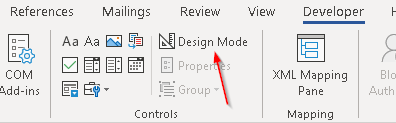

On the **Insert** tab, in the **Text **group, click **Quick Parts**. Select the `TitlePage` document part template.

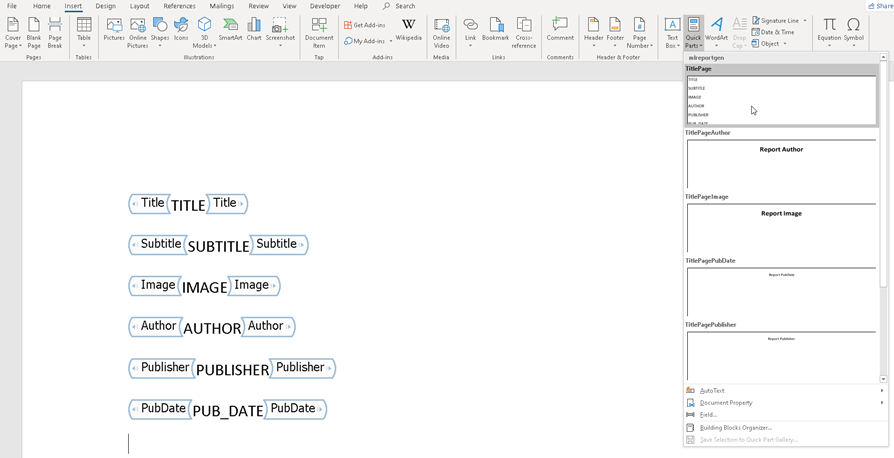

Select the content of the document part template. On the **Layout** tab, in the **Page Setup** group, click the **Page Setup** dialog box launcher. Modify the paper size and margins to A4 values:

- Top, bottom, left, right margins of 0.98 inches.

- Header and footer heights of 0.5 inches.

- Gutter size (space for binding pages) of 0.

- 8.27-inch by 11.69-inch page size in portrait orientation.

Click **OK** and close the dialog box.

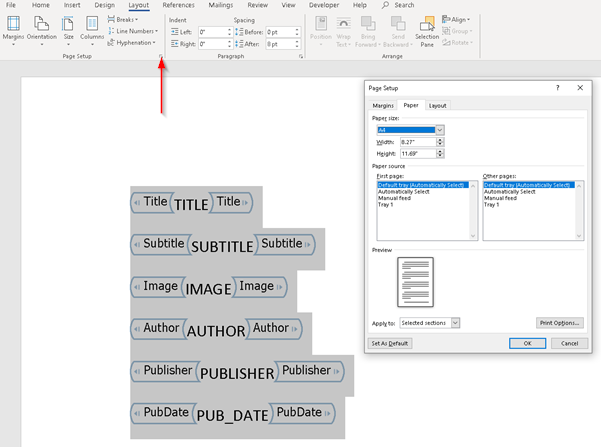

On the **Insert** tab, click **Quick Parts** and select **Save Selection to the Quick Part Gallery**.

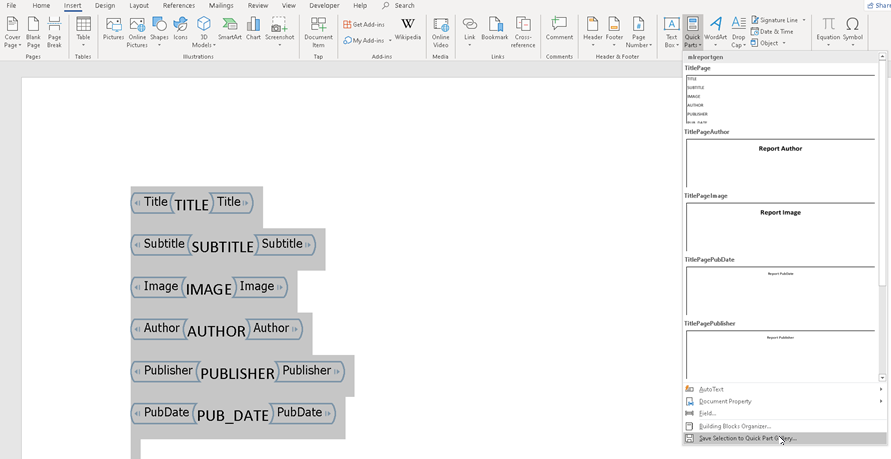

 In the Create New Building Block dialog box, enter the name of the document part template you modified, that is, `TitlePage` and select the `mlreportgen` category. Respond to the prompt to overwrite the previous version.

Select the content of the document part template, and save and close the template.

## **Customize the Table of Contents Word Template**

Create a copy of the` mlreportgen.report.TableOfContents` reporter default Word template.

mlreportgen.report.TableOfContents.createTemplate("tableOfContentsTemplate.dotx", "docx");

 In MATLAB, in the **Current Folder** pane, right-click the template file and click **Open Outside MATLAB**.

On the **Developer** tab, enable **Design Mode.** If the **Developer** tab is not available, click **File** > **Options**, and then click **Customize Ribbon**. Under **Main Tabs**, click the **Developer** check box. 

On the **Insert** tab, click **Quick Parts**. Select the `TableOfContents` document part template.

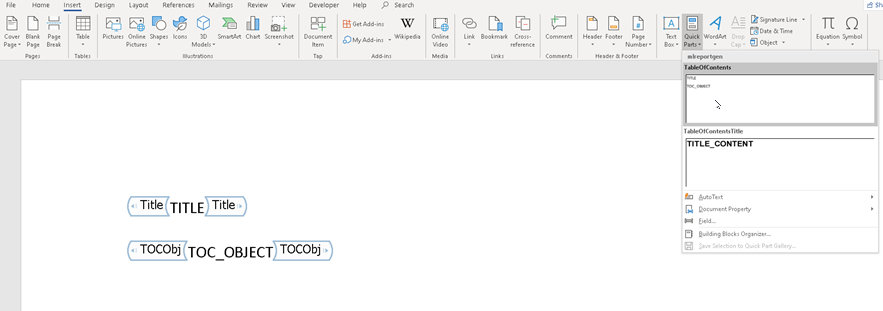

Select the content of the document part template. On the **Layout** tab, in the **Page Setup** group, click the **Page Setup** dialog box launcher. Modify the paper size and margins to the A4 values:

- Top, bottom,left,right margins of 0.98 inches.

- Header and footer heights of 0.5 inches.

- Gutter size (space for binding pages) of 0.

- 8.27-inch by 11.69-inch page size in portrait orientation.

Click **OK** and close the dialog box.

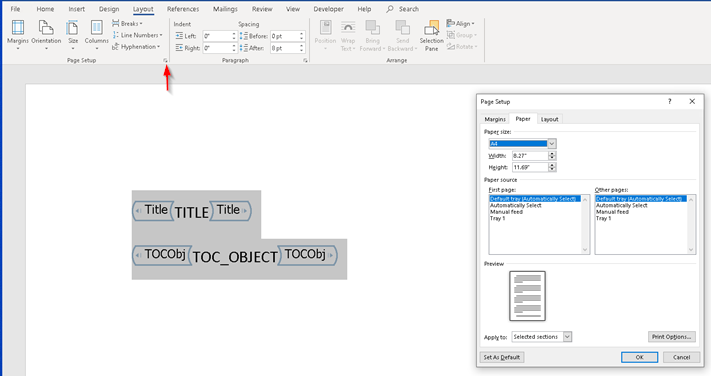

On the **Insert** tab, click **Quick Parts** and select **Save Selection to the Quick Part Gallery**.

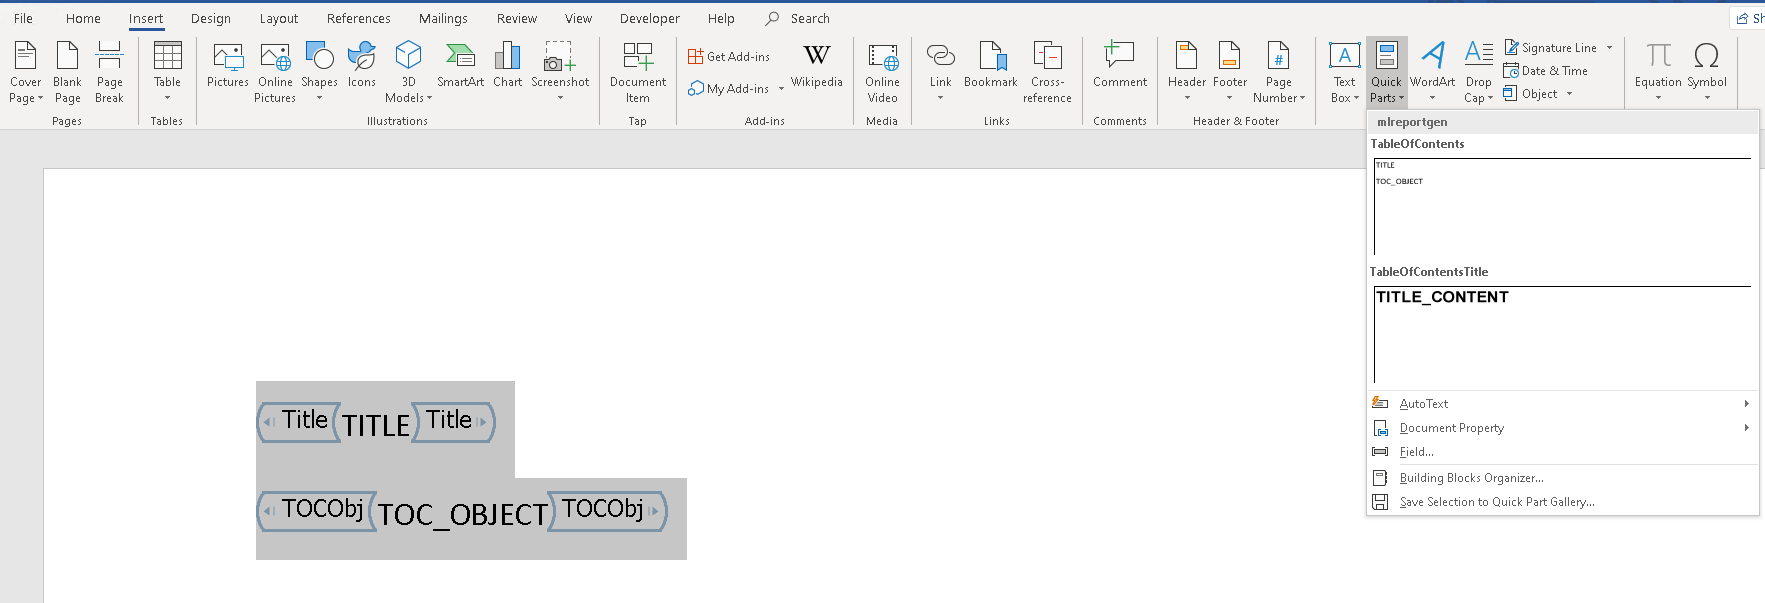

In the Create New Building Block dialog box, enter the name of the document part template you modified, that is, `TableOfContents` and select the `mlreportgen` category. Respond to the prompt to overwrite the previous version.

Delete the content of the document part template, and save and close the template.

## **Customize the Chapter Word Template**

Create a copy of the `mlreportgen.report.Chapter` reporter default Word template.

mlreportgen.report.Chapter.createTemplate("chapterTemplate.dotx", "docx");

In MATLAB®, in the **Current Folder** pane, right-click the template file and click **Open Outside MATLAB**.

On the **Developer** tab, enable **Design Mode.** If the **Developer** tab is not available, click **File** > **Options**, and then click **Customize Ribbon**. Under **Main Tabs**, click the **Developer** check box. 

On the **Insert** tab, click **Quick Parts**. Select the `Section1` document part template.

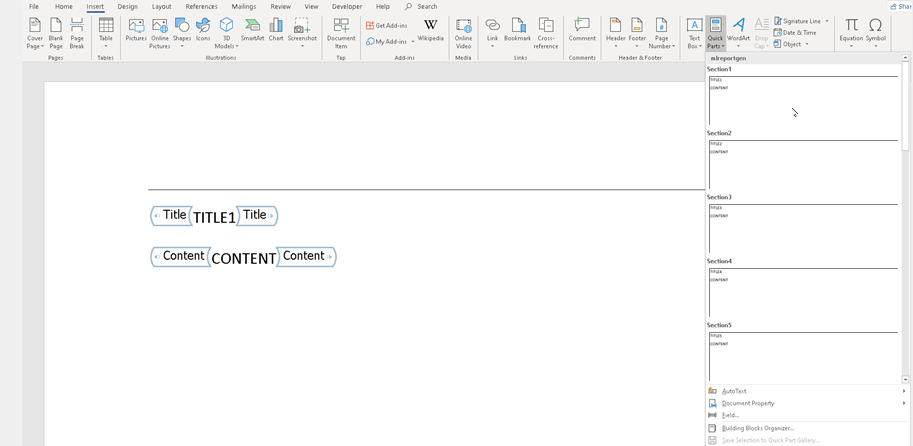

Select the content of the document part template. On the **Layout** tab, in the **Page Setup** group, click the **Page Setup** dialog box launcher. Modify the paper size and margins to the A4 values:

- Top, bottom,left,right margins of 0.98 inches.

- Header and footer heights of 0.5 inches.

- Gutter size (space for binding pages) of 0.

- 8.27-inch by 11.69-inch page size in portrait orientation.

Click **OK** and close the dialog box.

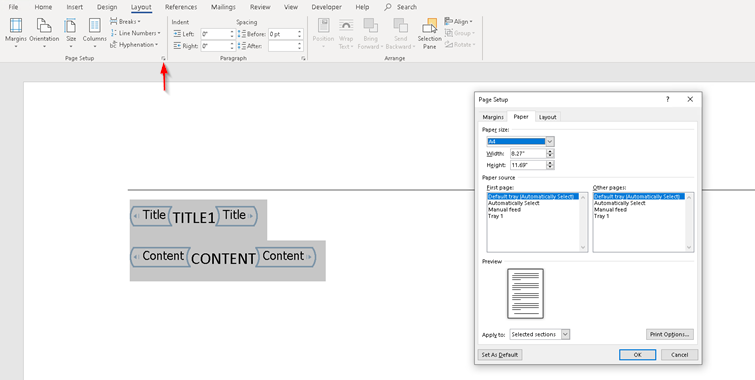

On the **Insert** tab, click **Quick Parts** and select **Save Selection to the Quick Part Gallery**.

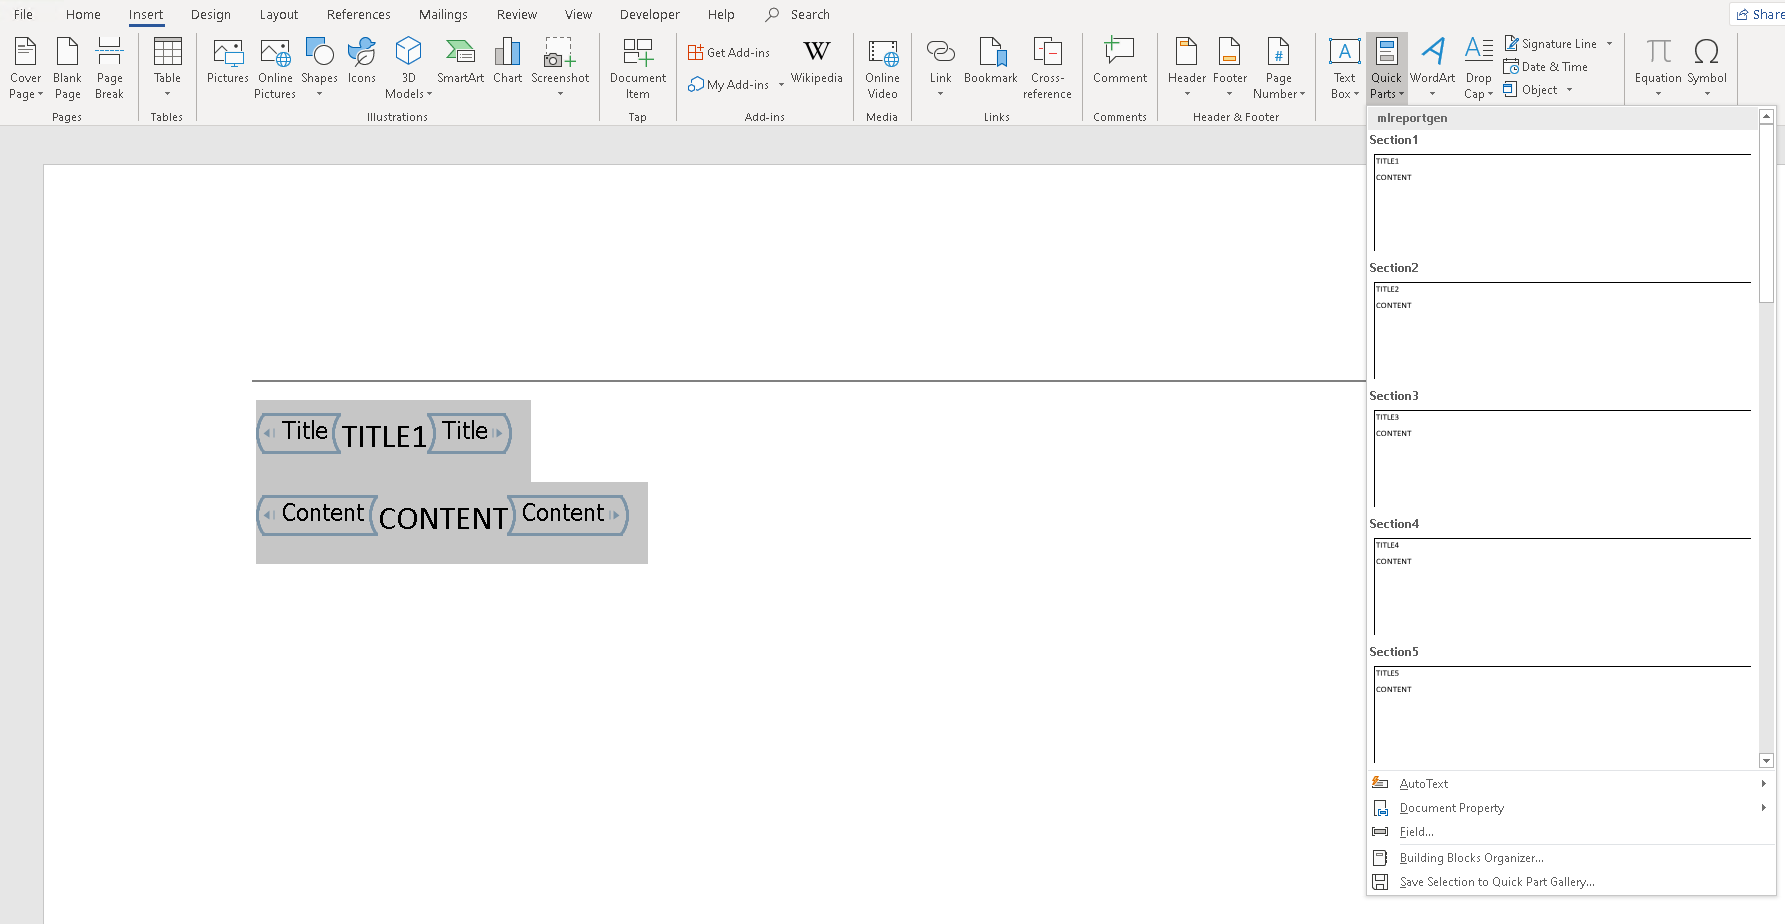

In the Create New Building Block dialog box, enter the name of the document part template you modified, that is, `Section1` and select the `mlreportgen` category. Respond to the prompt to overwrite the previous version.

Delete the content of the document part template, and save and close the template.

## **Use Customized Templates in a Report**

Use the customized template to create a Word report on magic squares, that is, matrices whose columns, rows, and diagonals each add up to the same number.

### **Import DOM and Report API Packages**

Import the DOM and Report API packages to avoid having to use fully qualified class names.

import mlreportgen.report.*;
import mlreportgen.dom.*;

Create a report container.

rpt = Report("report","docx");

### **Add a Title Page**

Create a title page and specify the title, subtitle, and author.

title = TitlePage("Title", "Magic Squares");
title.Subtitle = "Columns, Rows, Diagonals: All Equal Sums";
title.Author = "Albrecht Durer"; 

Use the custom title page template to generate the title page.

title.TemplateSrc= fullfile(pwd,"titlePageTemplate.dotx");

Add the title page to the report. 

append(rpt,title);

### **Add a Table of Contents**

toc = TableOfContents;

Use the custom table of contents template to generate the table of contents.

toc.TemplateSrc = fullfile(pwd,"tableOfContentsTemplate.dotx");

Add the table of contents to the report.

append(rpt,toc);

### **Add a Chapter**

Create a chapter and specify the title.

chapter = Chapter("Introduction"); 

Use the custom chapter template to generate the chapter.

chapter.TemplateSrc = fullfile(pwd,"chapterTemplate.dotx");

Create a section and add a paragraph to it. 

sec1 = Section("What is a Magic Square?"); 
para = Paragraph(['A magic square is an N-by-N matrix '... 
'constructed from the integers 1 through N^2 '... 
'with equal row, column, and diagonal sums.']); 
append(sec1,para) 

Add the section to the chapter.

append(chapter,sec1)

Create another section and add a paragraph to it.

sec2 = Section("Albrect Durer and the Magic Square"); 
para = Paragraph([ ... 
'The German artist Albrecht Durer (1471-1528) created '... 
'many woodcuts and prints with religious and '... 
'scientific symbolism. One of his most famous works, '... 
'Melancholia I, explores the depressed state of mind '... 
'which opposes inspiration and expression. '... 
'Renaissance astrologers believed that the Jupiter '... 
'magic square (shown in the upper right portion of '... 
'the image) could aid in the cure of melancholy. The '... 
'engraving''s date (1514) can be found in the '... 
'lower row of numbers in the square.']); 
append(sec2,para);

 Add the section to the chapter.

append(chapter,sec2);

Add the chapter to the report.

append(rpt,chapter);

### **Close and View the Document**

close(rpt);
rptview(rpt);

*Copyright 2020 The MathWorks, Inc.*